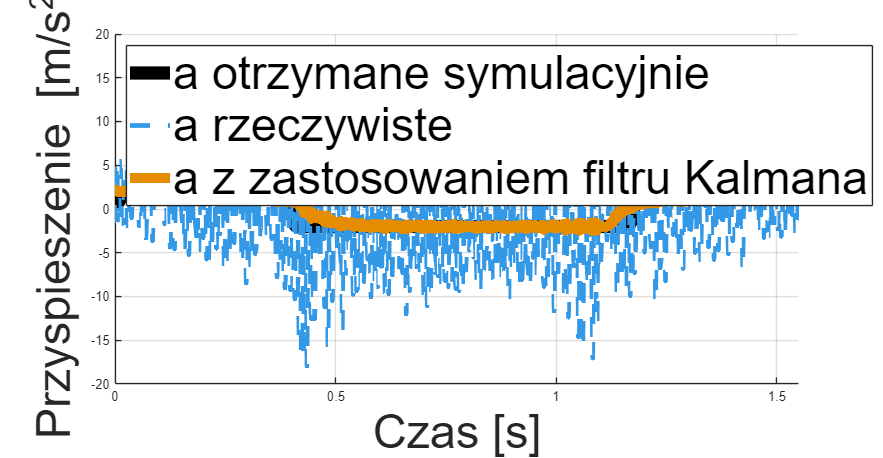

clc; clear; close all;

ur3 = loadrobot("universalUR3","DataFormat","row","Gravity",[0 0 -9.81]);
v_max_TCP = 1;
a_max_TCP = 2;
dt = 0.01;
max_allow_g = 9.81;

q_home = deg2rad([0, -90, -135, -45, 90, 0]);
q_end  = deg2rad([0, -90, -45, -135, 90, 0]);

T1 = getTransform(ur3, q_home, 'tool0');
T2 = getTransform(ur3, q_end, 'tool0');
pos1 = tform2trvec(T1);
pos2 = tform2trvec(T2);
rotm1 = tform2rotm(T1);
rotm2 = tform2rotm(T2);
d_TCP = norm(pos2 - pos1);

if d_TCP < 1e-6, error('Dystans TCP zerowy.'); end

t_acc_candidate = v_max_TCP / a_max_TCP;
d_acc_candidate = 0.5 * a_max_TCP * t_acc_candidate^2;
if d_TCP < 2*d_acc_candidate
    v_max_TCP = sqrt(a_max_TCP * d_TCP);
end

t_acc = v_max_TCP / a_max_TCP;
d_acc = 0.5 * a_max_TCP * t_acc^2;
if d_TCP < 2*d_acc
    t_acc = sqrt(d_TCP / a_max_TCP);
    d_acc = 0.5 * a_max_TCP * t_acc^2;
    t_flat = 0;
    trajTime = 2*t_acc;
else
    t_flat = (d_TCP - 2*d_acc)/v_max_TCP;
    trajTime = 2*t_acc + t_flat;
end

trajTimes_full = 0:dt:(2*trajTime);
s_full = zeros(size(trajTimes_full));
for i=1:length(trajTimes_full)
    t=trajTimes_full(i);
    if t<=trajTime
        if t<=t_acc
            s_full(i)=0.5*a_max_TCP*t^2;
        elseif t<=(t_acc+t_flat)
            s_full(i)=d_acc+v_max_TCP*(t-t_acc);
        else
            t_dec=t-(t_acc+t_flat);
            s_full(i)=d_acc+v_max_TCP*t_flat+v_max_TCP*t_dec-0.5*a_max_TCP*t_dec^2;
        end
    else
        t2=t-trajTime;
        if t2<=t_acc
            s_full(i)=d_TCP-0.5*a_max_TCP*t2^2;
        elseif t2<=(t_acc+t_flat)
            s_full(i)=d_TCP-(d_acc+v_max_TCP*(t2-t_acc));
        else
            t_dec2=t2-(t_acc+t_flat);
            s_full(i)=d_acc+v_max_TCP*t_flat+v_max_TCP*t_dec2-0.5*a_max_TCP*t_dec2^2;
            s_full(i)=max(0,d_TCP-s_full(i));
        end
    end
end

s_full=max(0,min(d_TCP,s_full));
s_norm_full=s_full/d_TCP;
interpPos_full=pos1+(pos2-pos1).*s_norm_full';
interpRotm_full=repmat(rotm1,1,1,length(trajTimes_full));

ik=inverseKinematics('RigidBodyTree',ur3);
weights=[0.5 0.5 0.5 1 1 1];
qTraj_full=zeros(length(trajTimes_full),6);
initialguess=q_home;
for i=1:length(trajTimes_full)
    T_des=trvec2tform(interpPos_full(i,:))*rotm2tform(interpRotm_full(:,:,i));
    [config,~]=ik('tool0',T_des,weights,initialguess);
    qTraj_full(i,:)=config;
    initialguess=config;
end
T_full=trajTimes_full;

Nfull=size(qTraj_full,1);
TCP_pos=zeros(Nfull,6);
for i=1:Nfull
    T=getTransform(ur3,qTraj_full(i,:),'tool0');
    TCP_pos(i,1:3)=tform2trvec(T);
    TCP_pos(i,4:6)=tform2eul(T);
end
TCP_vel=[zeros(1,6); diff(TCP_pos)/dt];
TCP_acc=[zeros(1,6); diff(TCP_vel)/dt];

qd_traj = [zeros(1,6); diff(qTraj_full)/dt];
qdd_traj = [zeros(1,6); diff(qd_traj)/dt];

rawText = fileread("W2_L_1000_2000-000.txt");
lines = strsplit(rawText, newline);
lines = lines(~startsWith(strtrim(lines), "//"));

tempFile = 'imu_clean.txt';
fid = fopen(tempFile, 'w');
fprintf(fid, '%s\n', lines{:});
fclose(fid);

imu = readtable(tempFile, 'FileType','text');

varsToConvert = {'PacketCounter','SampleTimeFine','Acc_X','Acc_Y','Acc_Z','Gyr_X','Gyr_Y','Gyr_Z'};
for v = varsToConvert
    if ismember(v{1}, imu.Properties.VariableNames)
        imu.(v{1}) = double(imu.(v{1}));
    end
end

dt_imu = 1/400;
t_imu = (0:dt_imu:(height(imu)-1)*dt_imu)';

acc_data = ([imu.Acc_X, imu.Acc_Y, imu.Acc_Z]/9.81+1)/2*20;
gyr_data = [imu.Gyr_X, imu.Gyr_Y, imu.Gyr_Z];

shiftSamples = 0;
acc_data_shifted = circshift(acc_data, shiftSamples);
gyr_data_shifted = circshift(gyr_data, shiftSamples);
acc_data_shifted(1:shiftSamples,:) = NaN;
gyr_data_shifted(1:shiftSamples,:) = NaN;
t_imu_shifted = t_imu;

offset = 2.44;

gZ = gyr_data_shifted(:,2);
aZ = acc_data_shifted(:,2);

firstNonNaN_g = find(~isnan(gZ),1,'first');
firstNonNaN_a = find(~isnan(aZ),1,'first');
if isempty(firstNonNaN_g), firstNonNaN_g = 1; end
if isempty(firstNonNaN_a), firstNonNaN_a = 1; end
gZ_init = gZ; aZ_init = aZ;
gZ_init(1:firstNonNaN_g-1) = gZ_init(firstNonNaN_g);
aZ_init(1:firstNonNaN_a-1) = aZ_init(firstNonNaN_a);

dt_kf = dt;
N = length(gZ_init);

idle_end = min(max(5, offset-1), floor(N/8));
if idle_end < 5
    idle_end = 5;
end
idle_end = min(idle_end, N);

gZ_idle = gZ_init(1:idle_end);
aZ_idle = aZ_init(1:idle_end);

V_g = max(0.01,var(gZ_idle));
V_a = max(0.01,var(aZ_idle));

W_g = (1)^2;
W_a = (2)^2;

xpost_g = zeros(N,1);
Ppost_g = zeros(N,1);
xpost_a = zeros(N,1);
Ppost_a = zeros(N,1);

xpost_g(1) = gZ_init(1);
Ppost_g(1) = 1;
xpost_a(1) = aZ_init(1);
Ppost_a(1) = 1;

A = 1; C = 1;

for k = 2:N
    xpri = A * xpost_g(k-1);
    Ppri = A * Ppost_g(k-1) * A' + V_g;
    yk = gZ_init(k);
    S = C * Ppri * C' + W_g;
    K = Ppri * C' / S;
    eps = yk - C * xpri;
    xpost_g(k) = xpri + K * eps;
    Ppost_g(k) = Ppri - K * S * K';

    xpri = A * xpost_a(k-1);
    Ppri = A * Ppost_a(k-1) * A' + V_a;
    yk = aZ_init(k);
    S = C * Ppri * C' + W_a;
    K = Ppri * C' / S;
    eps = yk - C * xpri;
    xpost_a(k) = xpri + K * eps;
    Ppost_a(k) = Ppri - K * S * K';
end

filtered_gZ = xpost_g;
filtered_aZ = xpost_a;

filtered_gZ(1:shiftSamples) = NaN;
filtered_aZ(1:shiftSamples) = NaN;

figure('Name','Przyspieszenia TCP vs Akcelerometr (surowe + Kalman)','Units','normalized','Position',[0.2 0.2 0.65 0.6]);
hold on;
h1 = plot(T_full, TCP_acc(:,3), '-', 'Color',[0 0 0], 'LineWidth',10);
h2 = plot((t_imu_shifted-offset), (acc_data_shifted(:,2)), '--', 'Color',[0.2 0.6 0.9], 'LineWidth',3.5);
h3 = plot((t_imu_shifted-offset), (filtered_aZ), '-', 'Color',[0.9 0.55 0.0], 'LineWidth',7.5);
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie [m/s^2]', 'FontSize', 35);
legend('a otrzymane symulacyjnie', 'a rzeczywiste','a z zastosowaniem filtru Kalmana','Location', 'Northwest', 'FontSize', 35);
grid on;
xlim([0 1.55])
hold off;


a_ref = TCP_acc(:,3);
t_ref = T_full(:);
a_meas = filtered_aZ(:);
t_meas = (t_imu_shifted(:) - offset);
valid_imu = ~isnan(a_meas) & ~isnan(t_meas);
t_meas = t_meas(valid_imu);
a_meas = a_meas(valid_imu);
commonRange = (t_ref >= min(t_meas)) & (t_ref <= max(t_meas));
t_common = t_ref(commonRange);
a_ref_common = a_ref(commonRange);
a_meas_interp = interp1(t_meas, a_meas, t_common, 'linear', 'extrap');
N_ref = length(a_ref_common);
N_meas = length(a_meas_interp);
N = min(N_ref, N_meas);
a_ref_common = a_ref_common(1:N);
a_meas_interp = a_meas_interp(1:N);
if isempty(a_ref_common)
    warning('Brak ważnych próbek do obliczenia funkcji celu I(a).');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_common - a_meas_interp));
end
fprintf('Wartość funkcji celu I(a): %.6f [m/s^2]\n', I_acc);

Wartość funkcji celu I(a): 0.505746 [m/s^2]


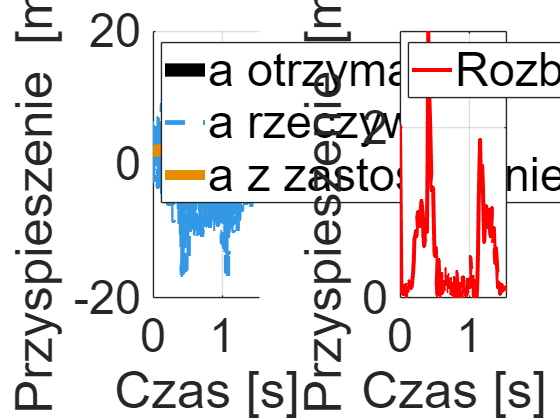


err_acc = a_meas_interp - a_ref_common;
err_acc_abs = abs(err_acc);
err_acc_plot = err_acc_abs;
err_acc_plot(isnan(err_acc_plot)) = 0;
figure();
subplot(1,2,1)
hold on;
h1 = plot(T_full, TCP_acc(:,3), '-', 'Color',[0 0 0], 'LineWidth',10);
h2 = plot((t_imu_shifted-offset), (acc_data_shifted(:,2)), '--', 'Color',[0.2 0.6 0.9], 'LineWidth',3.5);
h3 = plot((t_imu_shifted-offset), (filtered_aZ), '-', 'Color',[0.9 0.55 0.0], 'LineWidth',7.5);
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie [m/s^2]', 'FontSize', 35);
legend('a otrzymane symulacyjnie', 'a rzeczywiste','a z zastosowaniem filtru Kalmana','Location', 'Northwest', 'FontSize', 35);
grid on;
xlim([0 1.55])
set(gca, 'FontSize', 35);
hold off;

subplot(1,2,2)
plot(t_common, err_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie [m/s^2]', 'FontSize', 35);
legend('Rozbieżność a','Location', 'Northwest', 'FontSize', 35);
set(gca, 'FontSize', 35);
xlim([0 1.55]);